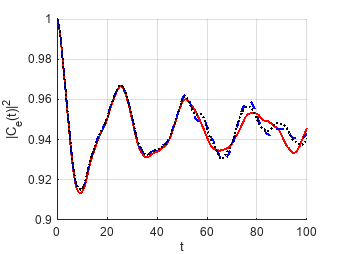

% Clear workspace, command window, and close all figures
clear;
clc;
close all;


% Parameters
N = 51; % Example value, you can change it
g = 0.1;   % Coupling strength g
J = 2;   % Coupling constant J
J_prime = 1; % Coupling constant J'
omega = 5; % Modulation frequency omega
Delta = omega * 0.5;  % Detuning parameter Delta
V = 0.2;   % Modulation amplitude V
j_0 = (N-1)/2;

dt = 0.005;  % Time step for numerical integration
T = 100;   % Total simulation time
% Tie vector
time = 0:dt:T;
num_steps = length(time);


% Define the Hamiltonian function
H_Full = @(t) H_full(t, N, J, J_prime, V, omega, g, Delta, j_0);
H_AB = @(t) H_ab(t, N, J, J_prime, V, omega, g, Delta, j_0);
H_UV = @(t) H_uv(t, N, J, J_prime, V, omega, g, Delta, j_0);
H_PQ = @(t) H_pq(t, N, J, J_prime, V, omega, g, Delta, j_0);

% Initialize the qubit in the excited state
psi_0 = zeros(2*N+1, 1);
psi_0(end) = 1;


% 调用runge_kutta_solver函数
psi_full = runge_kutta_timedependent(H_Full, psi_0, time);
psi_ab = runge_kutta_timedependent(H_AB, psi_0, time);
psi_uv = runge_kutta_timedependent(H_UV, psi_0, time);
psi_pq = runge_kutta_timedependent(H_PQ, psi_0, time);



% Plot |C_e(t)|^2 vs time
figure;
hold on;
plot(time, abs(psi_full(end, :)).^2, 'r', 'LineWidth', 1.5);
plot(time, abs(psi_ab(end, :)).^2, 'b--', 'LineWidth', 1.5);
plot(time, abs(psi_uv(end, :)).^2, 'g:', 'LineWidth', 1.5);
plot(time, abs(psi_pq(end, :)).^2, 'k:', 'LineWidth', 1.5);
xlabel('t');
ylabel('|C_{e}(t)|^2');
grid on;
hold off;

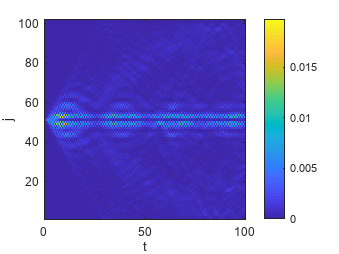


% Plot |C_x(t)|^2 vs t and x
figure;
imagesc(time, 1:2*N, abs(psi_full(1:end-1, :)).^2);
colorbar;
xlabel('t');
ylabel('j');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented

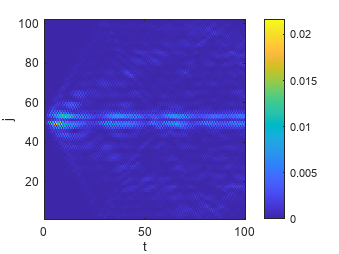



% |C_x(t)|^2 from H_pq
kk = linspace(-pi, pi, N);
E = sqrt((J^2 + J_prime^2) + 2*J*J_prime.*cos(kk));
theta = angle((J+J_prime.*exp(1i .* kk)) ./ E);
Gamma = (J+J_prime) * V .* sin(kk) ./ E;
delta = E - (omega / 2);
tilde_E = sqrt(delta.^2 + Gamma.^2);
phi = asin(Gamma ./ tilde_E);
phi = phi + (phi < 0) * pi;
phi(isnan(phi)) = 0;

% p,q ---> u',v'
psi_uv = zeros(2*N+1,num_steps);
for i = 1:N
    psi_uv(2*i-1,:) = cos(phi(i)/2) * psi_pq(2*i-1,:) + sin(phi(i)/2) * psi_pq(2*i,:);
    psi_uv(2*i,:) = -1i * (sin(phi(i)/2) * psi_pq(2*i-1,:) - cos(phi(i)/2) * psi_pq(2*i,:));
end


% rorating frame u' ---> u
rotating = zeros(2*N+1, num_steps);
tu = exp(- 1i * omega /2 .* time);
tv = exp(1i * omega /2 .* time);
rotating(1:2:2*N,:) = repmat(tu, N, 1);
rotating(2:2:2*N,:) = repmat(tv, N, 1);
psi_uv = rotating .* psi_uv;


% u,v ---> a,b
psi_ab = zeros(2*N+1,num_steps);
for i = 1:N
    psi_ab(2*i-1,:) = exp(-1i * theta(i)) * (psi_uv(2*i-1,:) - psi_uv(2*i,:)) / sqrt(2);
    psi_ab(2*i,:) = (psi_uv(2*i-1,:) + psi_uv(2*i,:)) / sqrt(2);
end


% Fourier transform a_k ---> a_x
psi_ab_x = zeros(2*N);
k = linspace(-pi, pi, N);
x = (-(N-1)/2:(N-1)/2)';
fft = exp(1i .* kron(x, k)) / sqrt(N);
for i = 1:num_steps
    psi_ab_x(1:2:2*N-1, i) = fft * psi_ab(1:2:2*N-1,i); % a_k ---> a_x
    psi_ab_x(2:2:2*N, i) = fft * psi_ab(2:2:2*N,i); % b_k ---> b_x
end

% Plot |B_j(t)|^2 as a heatmap
figure;
imagesc(time, 1:2*N, abs(psi_ab_x).^2);
colorbar;
xlabel('t');
ylabel('j');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented


% Define function for the derivative

function H = H_full(t, N, J, J_prime, V, omega, g, Delta, j_0)
    v = 2 * V * cos(omega * t);
    % Create the Hamiltonian matrix
    H = zeros(2*N + 1);  % Include additional state for the qubit
    for i = 1:N-1

        H(2*i-1, 2*i) = J + v;
        H(2*i, 2*i-1) = J + v;

        H(2*i,2*i+1) = J_prime - v;
        H(2*i+1,2*i) = J_prime - v;
    end
    
    % Coupling the qubit to the left end of the SSH chain
    H(2*j_0+1, end) = g;
    H(end, 2*j_0+1) = g;
    H(end, end) = Delta;
end

function H = H_ab(t, N, J, J_prime, V, omega, g, Delta, j_0)
    vt = 2 * V * cos(omega * t);
    kk = linspace(-pi, pi, N);
    J1 = J + vt;
    J2 = J_prime - vt;

    % Create the Hamiltonian matrix
    H = zeros(2*N + 1); % Include additional state for the qubit
    H(end, end) = Delta;
    for i = 1:1:N
        k = kk(i);
        H(2*i-1,2*i) = J1 + J2 * exp(1i * k); % a_k^+ b_k
        H(2*i,2*i-1) = J1 + J2 * exp(-1i * k); % a_k^+ b_k

        H(end, 2*i-1) = g / sqrt(N);
        H(2*i-1, end) = g / sqrt(N);

    end

end

function H = H_uv(t, N, J, J_prime, V, omega, g, Delta, j_0)
    kk = linspace(-pi, pi, N);
    E = sqrt(J^2 + J_prime^2 + 2*J*J_prime.*cos(kk));
    theta = angle((J+J_prime.*exp(1i .* kk)) ./ E);
    Gamma = (J+J_prime) * V .* sin(kk) ./ E;

    % Create the Hamiltonian matrix
    H = zeros(2*N + 1); % Include additional state for the qubit
    H(end, end) = Delta;
    for j = 1:1:N
        theta_k = theta(j);
        E_k = E(j);
        Gamma_k = Gamma(j);
        H(2*j-1,2*j-1) = E_k; %mode p_k^dagger p_k
        H(2*j-1,2*j) = 1i * Gamma_k * exp(-1i * omega * t); %mode p_k^dagger q_k
        H(2*j,2*j-1) = - 1i * Gamma_k * exp(1i * omega * t); %mode q_k^dagger p_k
        H(2*j,2*j) = - E_k; % mode q_k^dagger q_k
        
        H(end, 2*j-1) = g * exp(-1i * theta_k) / sqrt(2*N); %sigma^+ u_k
        H(2*j-1, end) = g * exp(1i * theta_k) / sqrt(2*N); %sigma^- u_k^+
        H(end, 2*j) = - g * exp(-1i * theta_k) / sqrt(2*N); %sigma^+ v_k
        H(2*j, end) = - g * exp(1i * theta_k) / sqrt(2*N); %sigma^- u_k^+


    end

end


function H = H_pq(t, N, J, J_prime, V, omega, g, Delta, j_0)

    kk = linspace(-pi, pi, N);
    E = sqrt((J^2 + J_prime^2) + 2*J*J_prime.*cos(kk));
    theta = angle((J+J_prime.*exp(1i .* kk)) ./ E);
    Gamma = (J+J_prime) * V .* sin(kk) ./ E;
    delta = E - (omega / 2);
    tilde_E = sqrt(delta.^2 + Gamma.^2);

    % Create the Hamiltonian matrix
    H = zeros(2*N + 1); % Include additional state for the qubit
    
    for j = 1:1:N
        theta_k = theta(j);
        delta_k = delta(j);
        tilde_Ek = tilde_E(j);
        if tilde_Ek == - delta_k
            up = 0; uq = 1;
            vp = 1; vq = 0;
        elseif tilde_Ek == delta_k || tilde_Ek == 0
            up = 1; uq = 0;
            vp = 0; vq = 1;
        else
            up = Gamma(j) / sqrt(2*tilde_Ek * (tilde_Ek - delta_k)); 
            uq = Gamma(j) / sqrt(2*tilde_Ek * (tilde_Ek + delta_k));
            vp = -1i * sqrt((tilde_Ek - delta_k) / 2/ tilde_Ek);
            vq = 1i * sqrt((tilde_Ek + delta_k) / 2/ tilde_Ek);
        end

        H(2*j-1,2*j-1) = tilde_Ek; %mode p_k
        H(2*j,2*j) = - tilde_Ek; % mode q_k
        
        H(end, 2*j-1) = g * exp(-1i * theta_k) * (up * exp(-1i * omega * t / 2) - vp * exp(1i * omega * t / 2)) / sqrt(2*N);
        H(2*j-1, end) = g * exp(1i * theta_k) * (conj(up) * exp(1i * omega * t / 2) - conj(vp) * exp(-1i * omega * t / 2)) / sqrt(2*N);
        H(end, 2*j) = g * exp(-1i * theta_k) * (uq * exp(-1i * omega * t / 2) - vq * exp(1i * omega * t / 2)) / sqrt(2*N);
        H(2*j, end) = g * exp(1i * theta_k) * (conj(uq) * exp(1i * omega * t / 2) - conj(vq) * exp(-1i * omega * t / 2)) / sqrt(2*N);

    end
    H(end, end) = Delta;
end



